clc,clear
I = imread('Fig0.tif');
sizeofI = size(I)

sizeofI =    256   256


## **1.Uniform noise**

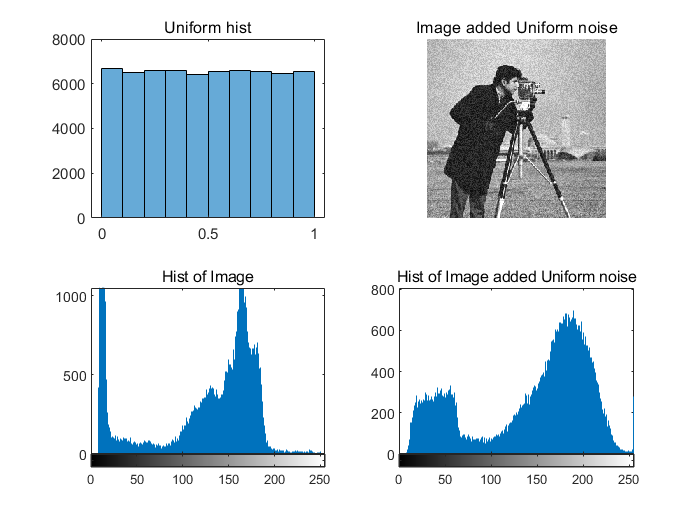

close all
noise1 = imnoise2('uniform',sizeofI(1),sizeofI(2),0,1);
subplot(2,2,1),histogram(noise1,10);title('Uniform hist');
subplot(2,2,2),imshow(I+uint8(noise1*50));title('Image added Uniform noise');
subplot(2,2,3),imhist(I),title('Hist of Image');
subplot(2,2,4),imhist(I+uint8(noise1*50)),title('Hist of Image added Uniform noise');

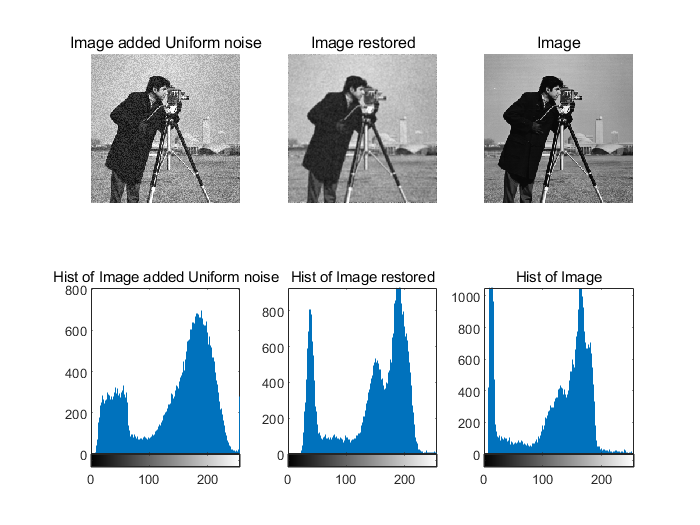

close all
imgNoise1 = I+uint8(noise1*50);
imgRes1 = ImgRestore(imgNoise1,'arithmetic mean',3,3);
subplot(2,3,1),imshow(imgNoise1),title('Image added Uniform noise')
subplot(2,3,2),imshow(imgRes1),title('Image restored')
subplot(2,3,3),imshow(I),title('Image');
subplot(2,3,4),imhist(imgNoise1),title('Hist of Image added Uniform noise');
subplot(2,3,5),imhist(imgRes1),title('Hist of Image restored');
subplot(2,3,6),imhist(I),title('Hist of Image');

## 2.Gaussian noise

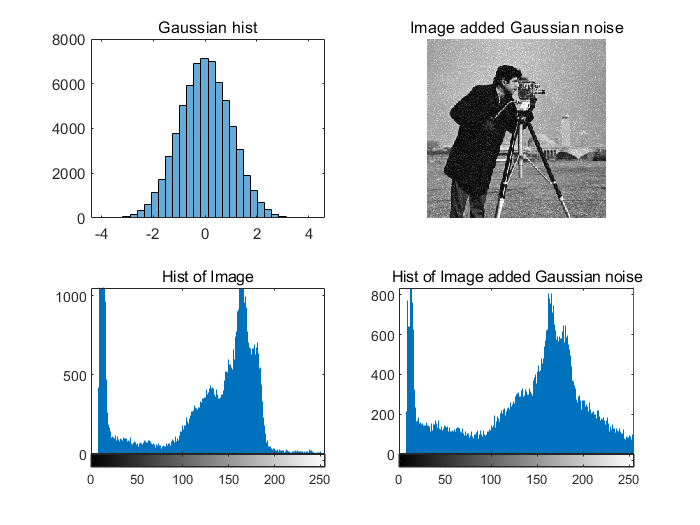

close all
noise2 = imnoise2('gaussian',sizeofI(1),sizeofI(2),0,1);
subplot(2,2,1),histogram(noise2,30);title('Gaussian hist');
subplot(2,2,2),imshow(I+uint8(noise2*20));title('Image added Gaussian noise');
subplot(2,2,3),imhist(I),title('Hist of Image');
subplot(2,2,4),imhist(I+uint8(noise2*50)),title('Hist of Image added Gaussian noise');

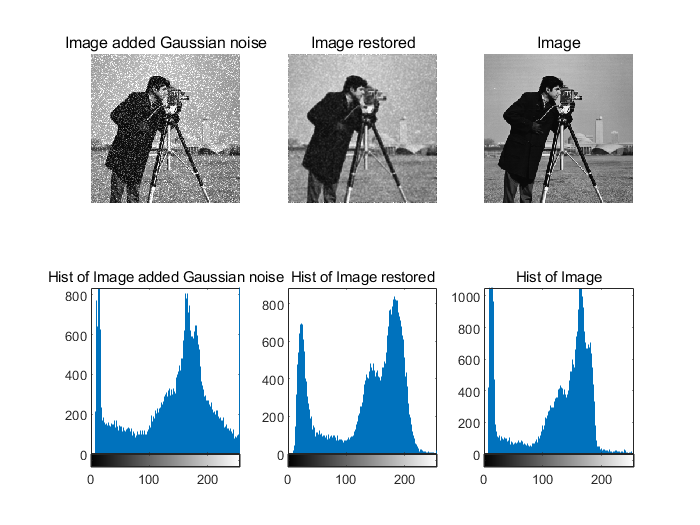

close all
imgNoise2 = I+uint8(noise2*50);
imgRes2 = ImgRestore(imgNoise2,'geometric mean',3,3);
subplot(2,3,1),imshow(imgNoise2),title('Image added Gaussian noise')
subplot(2,3,2),imshow(imgRes2),title('Image restored')
subplot(2,3,3),imshow(I),title('Image');
subplot(2,3,4),imhist(imgNoise2),title('Hist of Image added Gaussian noise');
subplot(2,3,5),imhist(imgRes2),title('Hist of Image restored');
subplot(2,3,6),imhist(I),title('Hist of Image');

## 3.Salt & pepper

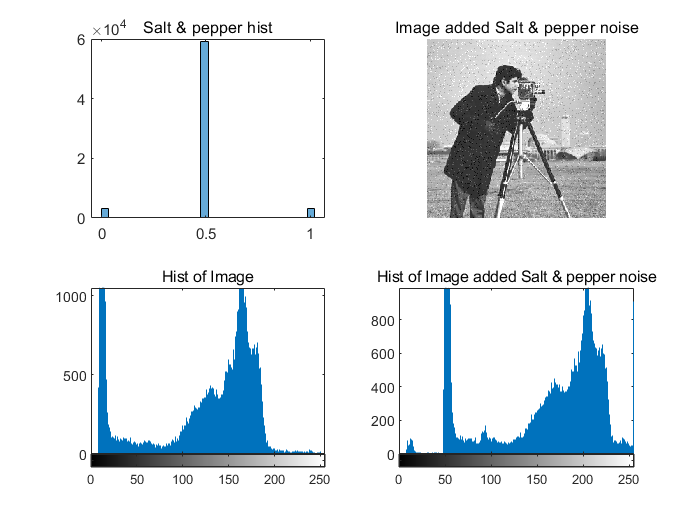

close all
noise3 = imnoise2('salt & pepper',sizeofI(1),sizeofI(2),0.05,0.05);
subplot(2,2,1),histogram(noise3,30);title('Salt & pepper hist');
subplot(2,2,2),imshow(I+uint8(noise3*80));title('Image added Salt & pepper noise');
subplot(2,2,3),imhist(I),title('Hist of Image');
subplot(2,2,4),imhist(I+uint8(noise3*80)),title('Hist of Image added Salt & pepper noise');

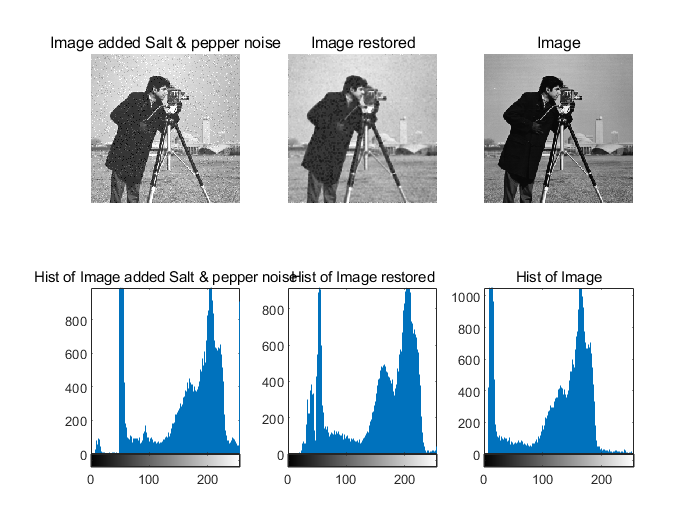

close all
imgNoise3 = I+uint8(noise3*80);
imgRes3 = ImgRestore(imgNoise3,'harmonic mean',3,3);
subplot(2,3,1),imshow(imgNoise3),title('Image added Salt & pepper noise')
subplot(2,3,2),imshow(imgRes3),title('Image restored')
subplot(2,3,3),imshow(I),title('Image');
subplot(2,3,4),imhist(imgNoise3),title('Hist of Image added Salt & pepper noise');
subplot(2,3,5),imhist(imgRes3),title('Hist of Image restored');
subplot(2,3,6),imhist(I),title('Hist of Image');

## 4.Lognormal

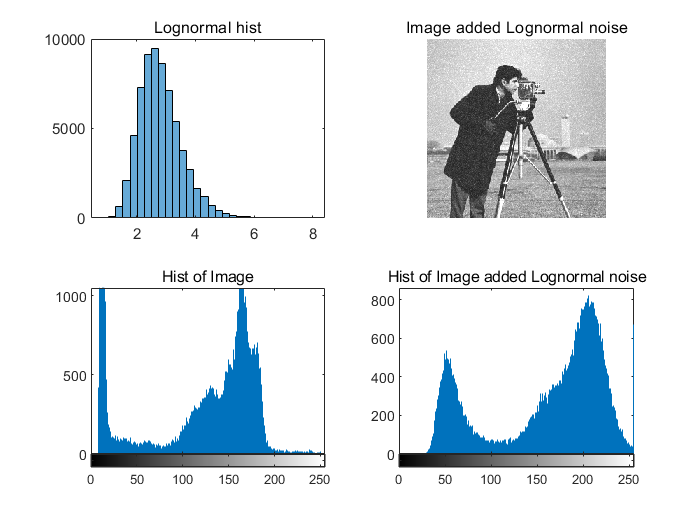

close all
noise4 = imnoise2('lognormal',sizeofI(1),sizeofI(2),1,0.25);
subplot(2,2,1),histogram(noise4,30);title('Lognormal hist');
subplot(2,2,2),imshow(I+uint8(noise4*15));title('Image added Lognormal noise');
subplot(2,2,3),imhist(I),title('Hist of Image');
subplot(2,2,4),imhist(I+uint8(noise4*15)),title('Hist of Image added Lognormal noise');

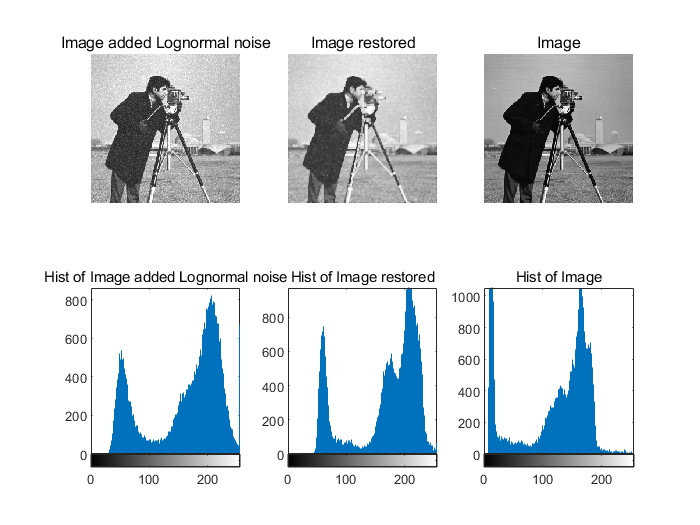

close all
imgNoise4 = I+uint8(noise4*15);
imgRes4 = ImgRestore(imgNoise4,'inverse harmonic mean',3,3,3);
subplot(2,3,1),imshow(imgNoise4),title('Image added Lognormal noise')
subplot(2,3,2),imshow(imgRes4),title('Image restored')
subplot(2,3,3),imshow(I),title('Image');
subplot(2,3,4),imhist(imgNoise4),title('Hist of Image added Lognormal noise');
subplot(2,3,5),imhist(imgRes4),title('Hist of Image restored');
subplot(2,3,6),imhist(I),title('Hist of Image');

## 5.Rayleigh

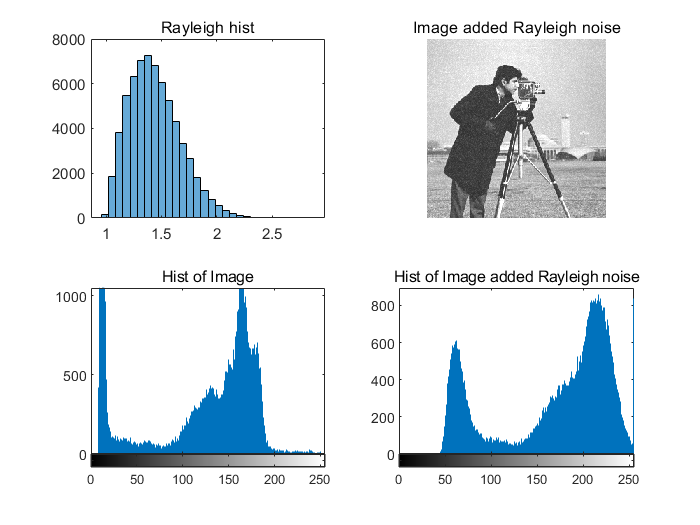

close all
noise5 = imnoise2('rayleigh',sizeofI(1),sizeofI(2),1,0.25);
subplot(2,2,1),histogram(noise5,30);title('Rayleigh hist');
subplot(2,2,2),imshow(I+uint8(noise5*35));title('Image added Rayleigh noise');
subplot(2,2,3),imhist(I),title('Hist of Image');
subplot(2,2,4),imhist(I+uint8(noise5*35)),title('Hist of Image added Rayleigh noise');

close all
imgNoise5 = I+uint8(noise5*35);
imgNoise5 = im2double(imgNoise5);
M = 2*size(I,1), N = 2*size(I,2)

M = 512

N = 512

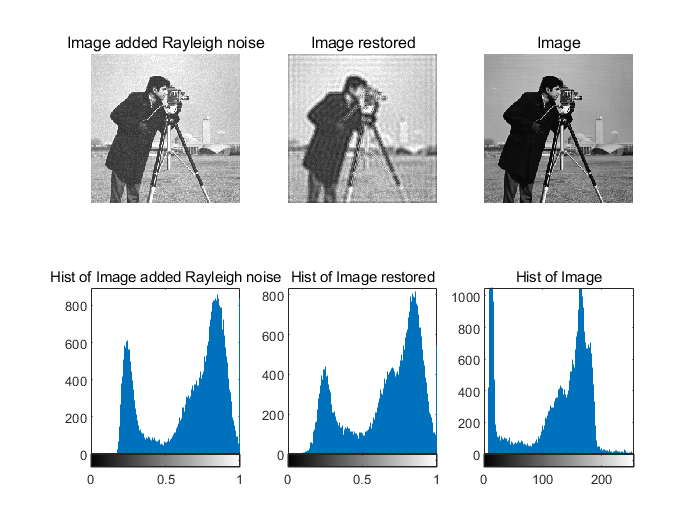

u = -M/2:(M/2-1);
v = -N/2:(N/2-1);
[U,V] = meshgrid(u, v);
D = sqrt(U.^2+V.^2);
D0 = 100;
W = 90;
Htemp1 = double(D<(D0-W/2));
Htemp2 = double(D>(D0+W/2));
H1 = Htemp1 + Htemp2;
J1 = fftshift(fft2(imgNoise5, size(H1, 1), size(H1, 2)));
K1 = J1.*H1; % 时域图像转换为频域
L1 = ifft2(ifftshift(K1));
L1 = L1(1:size(imgNoise5,1), 1:size(imgNoise5, 2)); % 频域图像转换为时频

subplot(2,3,1),imshow(imgNoise5),title('Image added Rayleigh noise')
subplot(2,3,2),imshow(L1),title('Image restored')
subplot(2,3,3),imshow(I),title('Image');
subplot(2,3,4),imhist(imgNoise5),title('Hist of Image added Rayleigh noise');
subplot(2,3,5),imhist(L1),title('Hist of Image restored');
subplot(2,3,6),imhist(I),title('Hist of Image');

## 6.Exponential

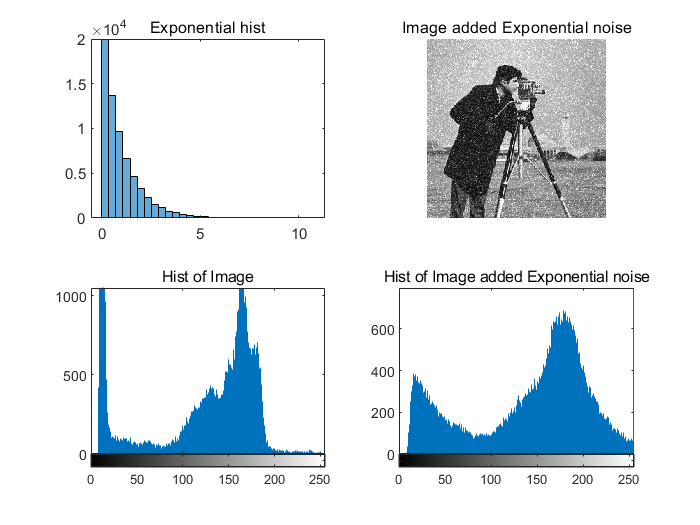

close all
noise6 = imnoise2('exponential',sizeofI(1),sizeofI(2),1,0.25);
subplot(2,2,1),histogram(noise6,30);title('Exponential hist');
subplot(2,2,2),imshow(I+uint8(noise6*25));title('Image added Exponential noise');
subplot(2,2,3),imhist(I),title('Hist of Image');
subplot(2,2,4),imhist(I+uint8(noise6*25)),title('Hist of Image added Exponential noise');

close all
imgNoise6 = I+uint8(noise6*25);
imgNoise6 = im2double(imgNoise6);
M = 2*size(I,1), N = 2*size(I,2)

M = 512

N = 512

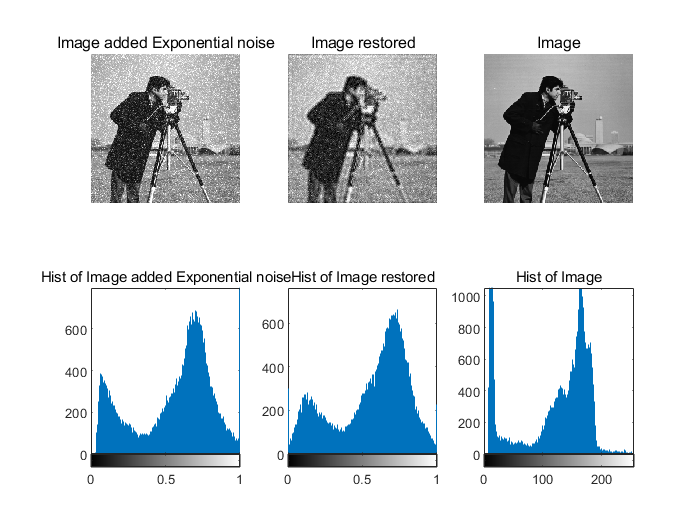

u = -M/2:(M/2-1);
v = -N/2:(N/2-1);
[U,V] = meshgrid(u, v);
D = sqrt(U.^2+V.^2);
D0 = 100;
n = 10;
H2 = 1./(1+(D*W./(D.^2-D0^2)).^(2*n));
J2 = fftshift(fft2(imgNoise6, size(H2, 1), size(H2, 2))); % 时域图像转换为频域
K2 = J2.*H2;
L2 = ifft2(ifftshift(K2)); % 频域图像转换为时频         
L2 = L2(1:size(imgNoise6,1), 1:size(imgNoise6, 2));


subplot(2,3,1),imshow(imgNoise6),title('Image added Exponential noise')
subplot(2,3,2),imshow(L2),title('Image restored')
subplot(2,3,3),imshow(I),title('Image');
subplot(2,3,4),imhist(imgNoise6),title('Hist of Image added Exponential noise');
subplot(2,3,5),imhist(L2),title('Hist of Image restored');
subplot(2,3,6),imhist(I),title('Hist of Image');

## 7.Erlang

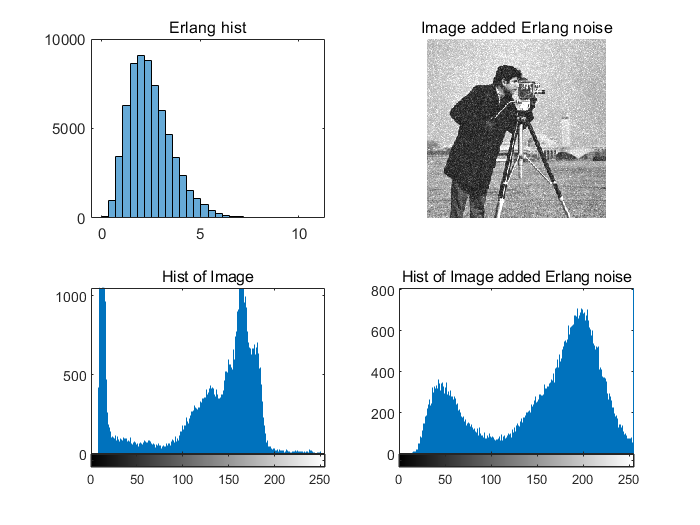

close all
noise7 = imnoise2('erlang',sizeofI(1),sizeofI(2),2,5);
subplot(2,2,1),histogram(noise7,30);title('Erlang hist');
subplot(2,2,2),imshow(I+uint8(noise7*15));title('Image added Erlang noise');
subplot(2,2,3),imhist(I),title('Hist of Image');
subplot(2,2,4),imhist(I+uint8(noise7*15)),title('Hist of Image added Erlang noise');

close all
imgNoise7 = I+uint8(noise7*15);
imgNoise7 = im2double(imgNoise7);
M = 2*size(I,1), N = 2*size(I,2)

M = 512

N = 512

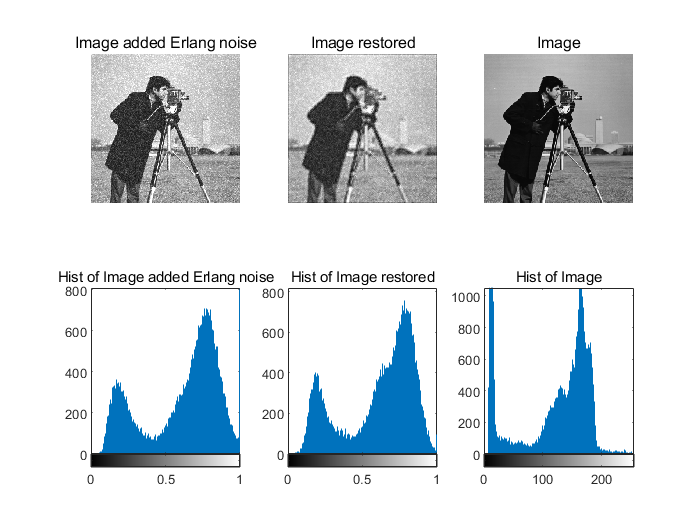

u = -M/2:(M/2-1);
v = -N/2:(N/2-1);
[U,V] = meshgrid(u, v);
D = sqrt(U.^2+V.^2);
D0 = 120;
W = 90;
H3 = 1 - exp(-1/2*((D.^2-D0^2)./(D*W)).^2);
J3 = fftshift(fft2(imgNoise7, size(H3, 1), size(H3, 2))); % 时域图像转换为频域
K3 = J3.*H3;
L3 = ifft2(ifftshift(K3)); % 频域图像转换为时频   
L3 = L3(1:size(imgNoise7,1), 1:size(imgNoise7, 2));

subplot(2,3,1),imshow(imgNoise7),title('Image added Erlang noise')
subplot(2,3,2),imshow(L3),title('Image restored')
subplot(2,3,3),imshow(I),title('Image');
subplot(2,3,4),imhist(imgNoise7),title('Hist of Image added Erlang noise');
subplot(2,3,5),imhist(L3),title('Hist of Image restored');
subplot(2,3,6),imhist(I),title('Hist of Image');

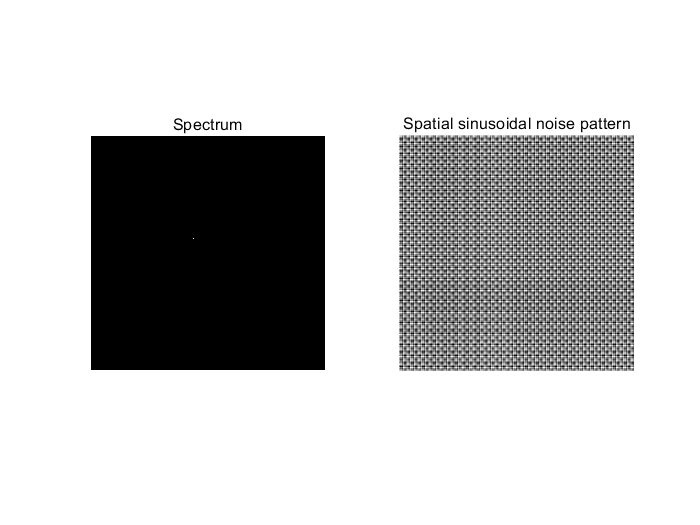

clc,clear,close all
C = [0 64;0 128;32 32;64 0;128 0;-32 32]; 
[r,R,S]=imnoise3(512,512,C);
figure
subplot(1,2,1),imshow(S,[]),title('Spectrum') % 显示频谱 
subplot(1,2,2),imshow(r,[]),title('Spatial sinusoidal noise pattern') % 显示空间正弦噪声模式 

C = [0 32;0 64;16 16;32 0;64 0;-16 16]; % 改变冲击位置，观察频谱和空间正弦噪声模式变化
figure
subplot(1,2,1),imshow(S,[]),title('Spectrum')
subplot(1,2,2),imshow(r,[]),title('Spatial sinusoidal noise pattern')

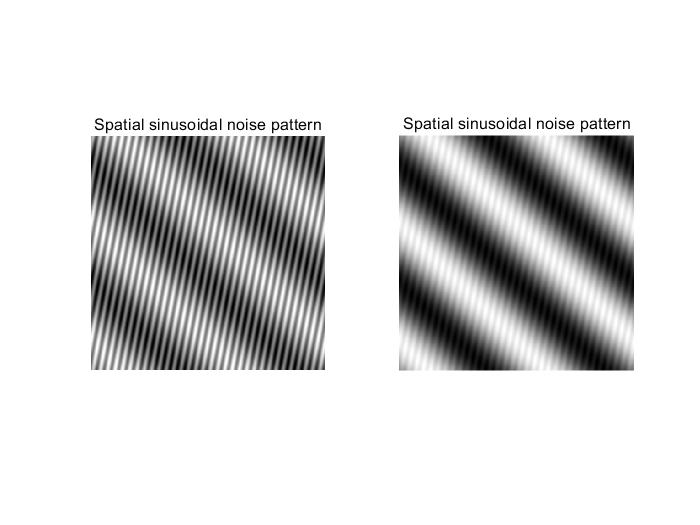

C = [6 32;-2 2]; % 改变冲击位置，观察空间正弦噪声模式变化 
[r,R,S]=imnoise3(512,512,C); 
figure
subplot(1,2,1),imshow(r,[]),title('Spatial sinusoidal noise pattern')
A=[1 10]; % 使用非默认振幅向量A,观察空间正弦噪声模式变化 
[r,R,S]=imnoise3(512,512,C,A); 
subplot(1,2,2),imshow(r,[]),title('Spatial sinusoidal noise pattern')

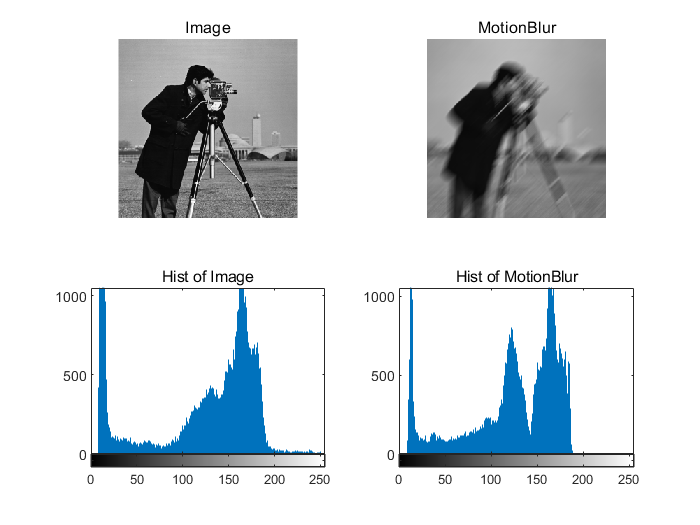

clc,clear,close all
I = imread('Fig0.tif');
hMotion = fspecial('motion',20,45);
MotionBlur = imfilter(I,hMotion,'replicate');
subplot(2,2,1),imshow(I),title('Image')
subplot(2,2,2),imshow(MotionBlur),title('MotionBlur')
subplot(2,2,3),imhist(I),title('Hist of Image');
subplot(2,2,4),imhist(MotionBlur),title('Hist of MotionBlur');

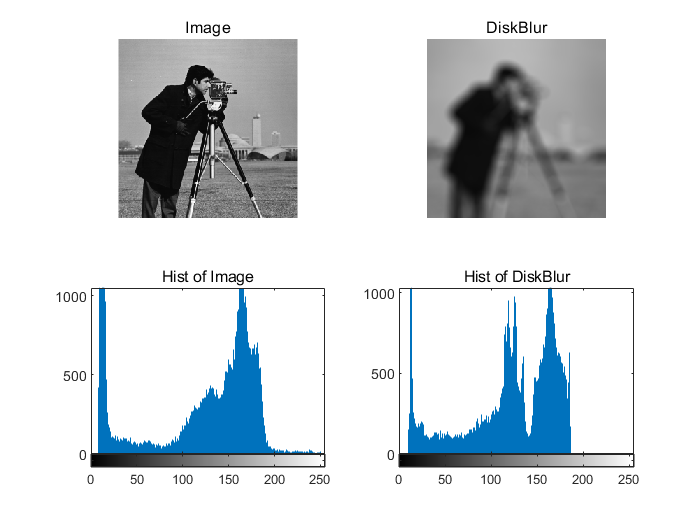

close all
hDisk = fspecial('disk',10);
DiskBlur = imfilter(I,hDisk,'replicate');
subplot(2,2,1),imshow(I),title('Image')
subplot(2,2,2),imshow(DiskBlur),title('DiskBlur')
subplot(2,2,3),imhist(I),title('Hist of Image');
subplot(2,2,4),imhist(DiskBlur),title('Hist of DiskBlur');

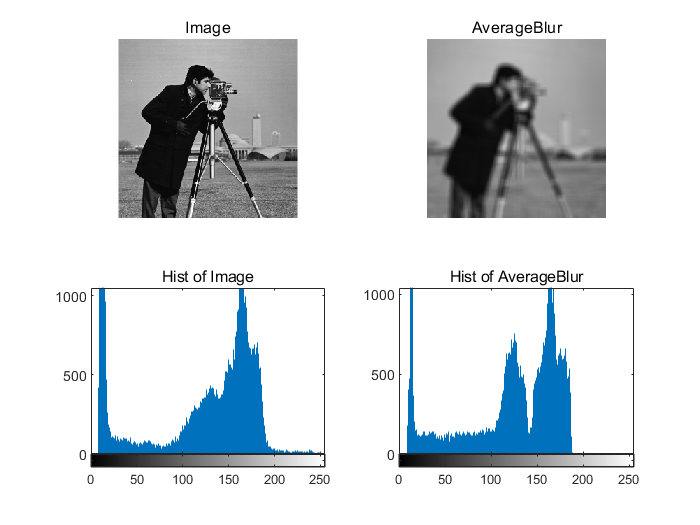

close all
hAverage = fspecial('average',10);
AverageBlur = imfilter(I,hAverage,'replicate');
subplot(2,2,1),imshow(I),title('Image')
subplot(2,2,2),imshow(AverageBlur),title('AverageBlur')
subplot(2,2,3),imhist(I),title('Hist of Image');
subplot(2,2,4),imhist(AverageBlur),title('Hist of AverageBlur');

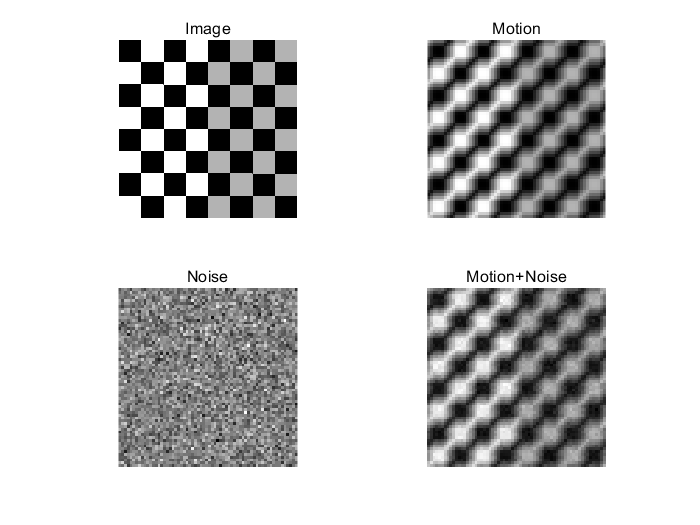

clc,clear,close all
f=checkerboard(8);
PSF=fspecial('motion',7,45);
gb=imfilter(f,PSF,'circular');
noise=imnoise2('Gaussian',size(f,1),size(f,2),0,sqrt(0.001));
g=gb+noise;
subplot(2,2,1),imshow(pixeldup(f,8),[]),title('Image')
subplot(2,2,2),imshow(pixeldup(gb,8),[]),title('Motion')
subplot(2,2,3),imshow(pixeldup(noise,8),[]),title('Noise')
subplot(2,2,4),imshow(pixeldup(g,8),[]),title('Motion+Noise')

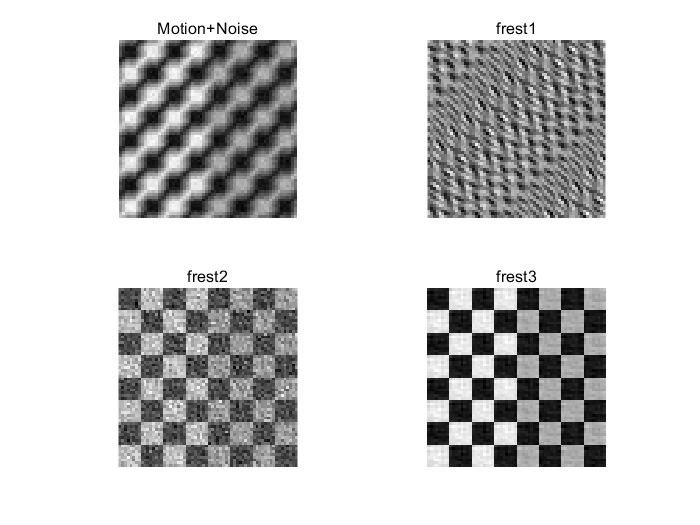

% Method 1
frest1 = deconvwnr(g,PSF);
% Method 2
Sn = abs(fft2(noise)).^2;
nA = sum(Sn(:))/numel(noise);
Sf = abs(fft2(f)).^2;
fA = sum(Sf(:))/numel(f);
R = nA/fA;
frest2 = deconvwnr(g,PSF,R);
% Method 3
NCORR = fftshift(real(ifft2(Sn)));
ICORR = fftshift(real(ifft2(Sf)));
frest3 = deconvwnr(g,PSF,NCORR,ICORR);
subplot(2,2,1),imshow(pixeldup(g,8),[]),title('Motion+Noise')
subplot(2,2,2),imshow(frest1,[]),title('frest1');
subplot(2,2,3),imshow(frest2,[]),title('frest2');
subplot(2,2,4),imshow(frest3,[]),title('frest3');

function restored = ImgRestore(img, method, M, N, Q)
img = double(img);
restored = img;
imgSize = size(img);
% filter is a MxN matrice
offset = (M-1)/2;
switch(method)
    case 'arithmetic mean'
        for i = 2:imgSize(1)-1
            for j = 2:imgSize(2)-1
                temp = img(i-offset:i+offset,j-offset:j+offset); % Get the MxN matrice
                restored(i,j) = sum(sum(temp))/(M*N);
            end
        end
    case 'geometric mean'
        for i = 2:imgSize(1)-1
            for j = 2:imgSize(2)-1
                temp = img(i-offset:i+offset,j-offset:j+offset); % Get the MxN matrice
                restored(i,j) = prod(prod(temp))^(1/(M*N));
            end
        end
    case 'harmonic mean'
        for i = 2:imgSize(1)-1
            for j = 2:imgSize(2)-1
                temp = img(i-offset:i+offset,j-offset:j+offset); % Get the MxN matrice
                restored(i,j) = (M*N)/(sum(sum(1./temp)));
            end
        end
    case 'inverse harmonic mean'
        for i = 2:imgSize(1)-1
            for j = 2:imgSize(2)-1
                temp = img(i-offset:i+offset,j-offset:j+offset); % Get the MxN matrice
                up = sum(sum(temp.^(Q+1)));
                down = sum(sum(temp.^Q));
                restored(i,j) = up/down;
            end
        end
end
restored = uint8(restored);
end